#### Задача 4.3.

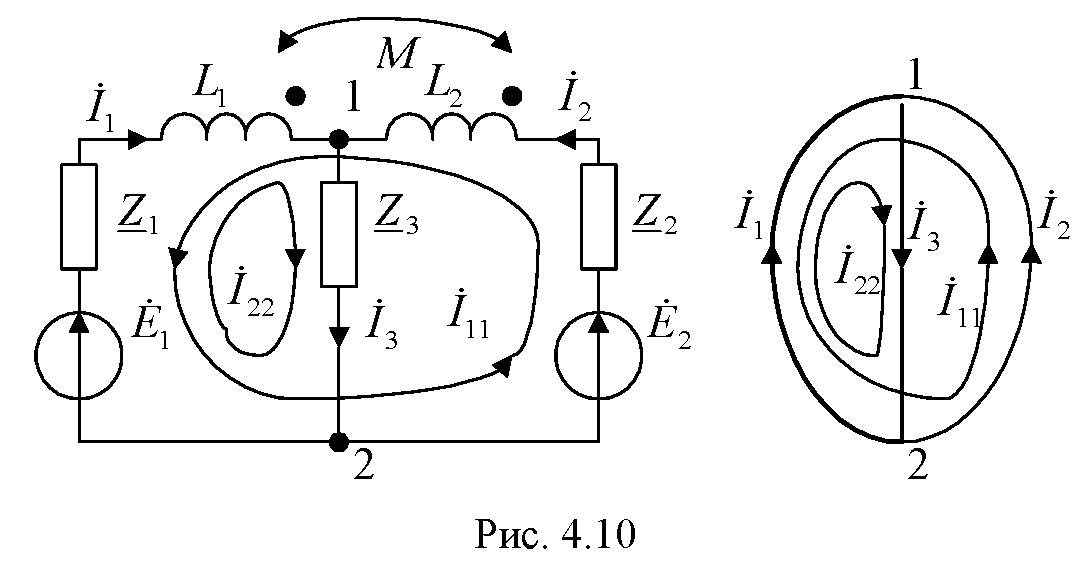

% Z1=10-8j Ом
% Z2=6 Ом
% Z3=-6j Ом
% XL1=6 Ом
% XL2=10 Ом
% k_C=0.85
% E1=50 В
% E2=50j В

clear
syms Z11 Z12 Z21 Z22 I11 I22 E11 E22

Уравнение в матричной форме

Zm=[Z11 Z12; Z21 Z22]

$$Zm = \left(\begin{array}{cc} Z_{11} & Z_{12}\\ Z_{21} & Z_{22} \end{array}\right)$$

Iv=[I11; I22]

$$Iv = \left(\begin{array}{c} I_{11}\\ I_{22} \end{array}\right)$$

Ev=[E11; E22]

$$Ev = \left(\begin{array}{c} E_{11}\\ E_{22} \end{array}\right)$$

Iv=Zm^(-1)*Ev

$$Iv = \left(\begin{array}{c} \frac{E_{11}\,Z_{22}}{Z_{11}\,Z_{22}-Z_{12}\,Z_{21}}-\frac{E_{22}\,Z_{12}}{Z_{11}\,Z_{22}-Z_{12}\,Z_{21}}\\ \frac{E_{22}\,Z_{11}}{Z_{11}\,Z_{22}-Z_{12}\,Z_{21}}-\frac{E_{11}\,Z_{21}}{Z_{11}\,Z_{22}-Z_{12}\,Z_{21}} \end{array}\right)$$

Z1=10-8j; Z2=6; Z3=-6j; X_L1=6; X_L2=10; k_C=0.85; E1=50; E2=50j;
digits(3)
X_M=vpa(k_C*sqrt(X_L1*X_L2))

$$X\_M = 6.58$$

% Z_M=j*X_M

Комплексное сопротивление взаимной индукции

Z_M=vpa(j*X_M)

$$Z\_M = 6.58\,\mathrm{i}$$

Собственные комплексные сопротивления контуров

Z11=vpa(Z1+Z2+j*(X_L1+X_L2)+2*Z_M)

$$Z11 = 16.0+21.2\,\mathrm{i}$$

Z22=vpa(Z1+j*X_L1+Z3)

$$Z22 = 10.0-8.0\,\mathrm{i}$$

Общие комплексные сопротивления контуров

Z12=vpa(-Z1-j*X_L1-Z_M), Z21=Z12

$$Z12 = -10.0-4.58\,\mathrm{i}$$

$$Z21 = -10.0-4.58\,\mathrm{i}$$

E11=vpa(-E1+E2), E22=vpa(E1)

$$E11 = -50.0+50.0\,\mathrm{i}$$

$$E22 = 50.0$$

Подставив данные, матричное уравнение принимает вид

Zm=[Z11 Z12; Z21 Z22]

$$Zm = \left(\begin{array}{cc} 16.0+21.2\,\mathrm{i} & -10.0-4.58\,\mathrm{i}\\ -10.0-4.58\,\mathrm{i} & 10.0-8.0\,\mathrm{i} \end{array}\right)$$

Ev=[E11; E22]

$$Ev = \left(\begin{array}{c} -50.0+50.0\,\mathrm{i}\\ 50.0 \end{array}\right)$$

Его решение

Iv=Zm^(-1)*Ev

$$Iv = \left(\begin{array}{c} 1.45+4.56\,\mathrm{i}\\ 0.113+5.31\,\mathrm{i} \end{array}\right)$$

Значения контурных токов

I11=vpa(Iv(1)),I22=vpa(Iv(2))

$$I11 = 1.45+4.56\,\mathrm{i}$$

$$I22 = 0.113+5.31\,\mathrm{i}$$

Токи ветвей

I2=I11, Ip2=vpa([abs(I2),angle(I2)*180/pi])

$$I2 = 1.45+4.56\,\mathrm{i}$$

$$Ip2 = \left(\begin{array}{cc} 4.78 & 72.3 \end{array}\right)$$

I3=I22, Ip3=vpa([abs(I3),angle(I3)*180/pi])

$$I3 = 0.113+5.31\,\mathrm{i}$$

$$Ip3 = \left(\begin{array}{cc} 5.31 & 88.8 \end{array}\right)$$

I1=-I11+I22, Ip1=vpa([abs(I1),angle(I1)*180/pi])

$$I1 = -1.34+0.756\,\mathrm{i}$$

$$Ip1 = \left(\begin{array}{cc} 1.54 & 151.0 \end{array}\right)$$

Напряжения на элементах ветвей

U_XL1=j*X_L1*I1

$$U\_XL1 = -4.54-8.03\,\mathrm{i}$$

U_1M=j*X_M*I2

$$U\_1M = -30.0+9.56\,\mathrm{i}$$

U_Z1=I1*Z1

$$U\_Z1 = -7.34+18.3\,\mathrm{i}$$

U_XL2=j*X_L2*I2

$$U\_XL2 = -45.6+14.5\,\mathrm{i}$$

U_2M=j*X_M*I1

$$U\_2M = -4.98-8.82\,\mathrm{i}$$

U_Z2=I2*Z2

$$U\_Z2 = 8.71+27.3\,\mathrm{i}$$

U3=I3*Z3

$$U3 = 31.9-0.678\,\mathrm{i}$$

Для расчета баланса мощностей определяем напряжения

U1=I1*(Z1+j*X_L1)-I2*Z_M

$$U1 = 18.1+0.678\,\mathrm{i}$$

U2=I2*(Z2+j*X_L2)-I1*Z_M

$$U2 = -31.9+50.7\,\mathrm{i}$$

U3=I3*Z3

$$U3 = 31.9-0.678\,\mathrm{i}$$

Комплексные мощности источников

S_ist=E1*I1'+E2*I2'

$$S\_ist = 161.0+34.8\,\mathrm{i}$$

и нагрузок

S_nagr=U1*I1'+U2*I2'+U3*I3'

$$S\_nagr = 161.0+34.8\,\mathrm{i}$$

Баланс мощностей выполняется.

Методом узловых напряжений.

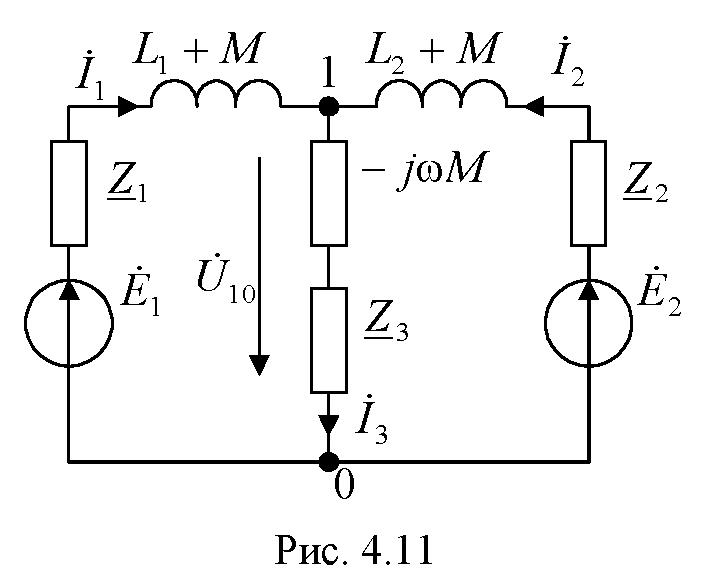

Узловое уравнение имеет вид

syms U10
eq1=U10*(1/(Z1+j*(X_L1+X_M))+1/(Z2+j*(X_L2+X_M))+1/(Z3-j*X_M))== ...
    E1/(Z1+j*(X_L1+X_M))+E2/(Z2+j*(X_L2+X_M))

$$eq1 = U_{10}\,\left(0.102-0.0117\,\mathrm{i}\right)=6.8-0.929\,\mathrm{i}$$

U10sol=vpa(solve(eq1,U10)), U10=U10sol

$$U10sol = 66.9-1.42\,\mathrm{i}$$

$$U10 = 66.9-1.42\,\mathrm{i}$$

I1=(E1-U10)/(Z1+j*(X_L1+X_M)), Ip1=vpa([abs(I1),angle(I1)*180/pi])

$$I1 = -1.34+0.756\,\mathrm{i}$$

$$Ip1 = \left(\begin{array}{cc} 1.54 & 151.0 \end{array}\right)$$

I2=(E2-U10)/(Z2+j*(X_L2+X_M)), Ip2=vpa([abs(I2),angle(I2)*180/pi])

$$I2 = 1.45+4.56\,\mathrm{i}$$

$$Ip2 = \left(\begin{array}{cc} 4.78 & 72.3 \end{array}\right)$$

I3=U10/(Z3-j*X_M), Ip3=vpa([abs(I3),angle(I3)*180/pi])

$$I3 = 0.113+5.31\,\mathrm{i}$$

$$Ip3 = \left(\begin{array}{cc} 5.31 & 88.8 \end{array}\right)$$

Решение методом контурных токов и использованием топологических формул.

Для графа на рис.4.10 записываем матрицы:

главных контуров

B=[-1 1 0; 1 0 1]

B =     -1     1     0
     1     0     1


ЭДС ветвей

Eb=vpa([E1;E2;0])

$$Eb = \left(\begin{array}{c} 50.0\\ 50.0\,\mathrm{i}\\ 0 \end{array}\right)$$

комплексных сопротивлений ветвей

Zb=[Z1+j*X_L1, -j*X_M, 0; -j*X_M, Z2+j*X_L2, 0; 0, 0, Z3]

$$Zb = \left(\begin{array}{ccc} 10-2\,\mathrm{i} & -6.58\,\mathrm{i} & 0\\ -6.58\,\mathrm{i} & 6+10\,\mathrm{i} & 0\\ 0 & 0 & -6\,\mathrm{i} \end{array}\right)$$

Znn=B*Zb*B'

$$Znn = \left(\begin{array}{cc} 16.0+21.2\,\mathrm{i} & -10.0-4.58\,\mathrm{i}\\ -10.0-4.58\,\mathrm{i} & 10-8\,\mathrm{i} \end{array}\right)$$

Enn=B*Eb

$$Enn = \left(\begin{array}{c} -50.0+50.0\,\mathrm{i}\\ 50.0 \end{array}\right)$$

Inn=Znn^(-1)*Enn

$$Inn = \left(\begin{array}{c} 1.45+4.56\,\mathrm{i}\\ 0.113+5.31\,\mathrm{i} \end{array}\right)$$

Ib=B'*Inn

$$Ib = \left(\begin{array}{c} -1.34+0.756\,\mathrm{i}\\ 1.45+4.56\,\mathrm{i}\\ 0.113+5.31\,\mathrm{i} \end{array}\right)$$

i1=Ib(1), Ip1=vpa([abs(i1),angle(i1)*180/pi])

$$i1 = -1.34+0.756\,\mathrm{i}$$

$$Ip1 = \left(\begin{array}{cc} 1.54 & 151.0 \end{array}\right)$$

i2=Ib(2), Ip2=vpa([abs(i2),angle(i2)*180/pi])

$$i2 = 1.45+4.56\,\mathrm{i}$$

$$Ip2 = \left(\begin{array}{cc} 4.78 & 72.3 \end{array}\right)$$

i3=Ib(3), Ip3=vpa([abs(i3),angle(i3)*180/pi])

$$i3 = 0.113+5.31\,\mathrm{i}$$

$$Ip3 = \left(\begin{array}{cc} 5.31 & 88.8 \end{array}\right)$$

U=Zb*Ib

$$U = \left(\begin{array}{c} 18.1+0.678\,\mathrm{i}\\ -31.9+50.7\,\mathrm{i}\\ 31.9-0.678\,\mathrm{i} \end{array}\right)$$

u1=U(1), Up1=vpa([abs(u1),angle(u1)*180/pi])

$$u1 = 18.1+0.678\,\mathrm{i}$$

$$Up1 = \left(\begin{array}{cc} 18.1 & 2.14 \end{array}\right)$$

u2=U(2), Up2=vpa([abs(u2),angle(u2)*180/pi])

$$u2 = -31.9+50.7\,\mathrm{i}$$

$$Up2 = \left(\begin{array}{cc} 59.9 & 122.0 \end{array}\right)$$

u3=U(3), Up1=vpa([abs(u3),angle(u3)*180/pi])

$$u3 = 31.9-0.678\,\mathrm{i}$$

$$Up1 = \left(\begin{array}{cc} 31.9 & -1.22 \end{array}\right)$$

Баланс мощностей:

комплексная мощность источников

Se=(Eb'*Ib)'

$$Se = 161.0+34.8\,\mathrm{i}$$

комплексаня мощность нагрузок

Sz=(U'*Ib)'

$$Sz = 161.0+34.8\,\mathrm{i}$$